rawDataPath_cells_media = '/home/mxwbio/Data/JG_25_12_08_M231s/251208/003425/Record/000002/data.raw.h5';
rawDataPath_media_media = '/home/mxwbio/Data/JG_25_12_08_M231s/251208/003486/Record/000001/data.raw.h5';

rawDataPath_cells_T0 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000006/data.raw.h5';
rawDataPath_cells_T30 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000010/data.raw.h5';
rawDataPath_cells_T60 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000014/data.raw.h5';

rawDataPath_cells_D1 = '/home/mxwbio/Data/JG_25_12_08_M231s/251216/P003425/Record/000018/data.raw.h5';
rawDataPath_cells_D2 = '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003425/Record/000026/data.raw.h5';
rawDataPath_cells_D3 = '/home/mxwbio/Data/JG_25_12_08_M231s/251218/P003425/Record/000030/data.raw.h5';
rawDataPath_cells_D4 = '/home/mxwbio/Data/JG_25_12_08_M231s/251219/P003425/Record/000038/data.raw.h5';

rawDataPath_media_T0 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000008/data.raw.h5';
rawDataPath_media_T30 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000012/data.raw.h5';
rawDataPath_media_T60 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000016/data.raw.h5';

rawDataPath_media_D1 = '/home/mxwbio/Data/JG_25_12_08_M231s/251216/P003486/Record/000020/data.raw.h5';
rawDataPath_media_D2 = '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003486/Record/000025/data.raw.h5';
rawDataPath_media_D3 = '/home/mxwbio/Data/JG_25_12_08_M231s/251218/P003486/Record/000032/data.raw.h5';
rawDataPath_media_D4 = '/home/mxwbio/Data/JG_25_12_08_M231s/251219/P003486/Record/000040/data.raw.h5';

rawData_cells_media = mxw.fileManager(rawDataPath_cells_media);
rawData_cells_T0 = mxw.fileManager(rawDataPath_cells_T0);
rawData_cells_T30 = mxw.fileManager(rawDataPath_cells_T30);
rawData_cells_T60 = mxw.fileManager(rawDataPath_cells_T60);

rawData_cells_D1 = mxw.fileManager(rawDataPath_cells_D1);
rawData_cells_D2 = mxw.fileManager(rawDataPath_cells_D2);
rawData_cells_D3 = mxw.fileManager(rawDataPath_cells_D3);
rawData_cells_D4 = mxw.fileManager(rawDataPath_cells_D4);

rawData_media_media = mxw.fileManager(rawDataPath_media_media);
rawData_media_T0 = mxw.fileManager(rawDataPath_media_T0);
rawData_media_T30 = mxw.fileManager(rawDataPath_media_T30);
rawData_media_T60 = mxw.fileManager(rawDataPath_media_T60);

rawData_media_D1 = mxw.fileManager(rawDataPath_media_D1);
rawData_media_D2 = mxw.fileManager(rawDataPath_media_D2);
rawData_media_D3 = mxw.fileManager(rawDataPath_media_D3);
rawData_media_D4 = mxw.fileManager(rawDataPath_media_D4);


electrodes = 1:966;
numSeconds = 1;

avPSD_RMSs_media = zeros(7,1);
avPSD_RMSs_cells = zeros(7,1);

timepoints = [(1/60) (30/60) (60/60) 24 48 72 96];

[PSD_cells_media,freq,PSDs_cells_media,~,~] = processRawData(rawData_cells_media,electrodes,numSeconds,2,0);

     1.995602646887605e-06



[PSD_cells_T0,~,PSDs_cells_T0,avPSD_RMSs_cells(1),diff_PSDs_cells_T0,diff_PSD_cells_T0] = processRawData(rawData_cells_T0,electrodes,numSeconds,0.5,0);

     2.282505728574063e-06



[PSD_cells_T30,~,PSDs_cells_T30,avPSD_RMSs_cells(2),diff_PSDs_cells_T30,diff_PSD_cells_T30] = processRawData(rawData_cells_T30,electrodes,numSeconds,0.5,PSDs_cells_T0);

     2.463162419824023e-06



[PSD_cells_T60,~,PSDs_cells_T60,avPSD_RMSs_cells(3),diff_PSDs_cells_T60,diff_PSD_cells_T60] = processRawData(rawData_cells_T60,electrodes,numSeconds,0.5,PSDs_cells_T0);

     2.409554763319858e-06



[PSD_cells_D1,~,PSDs_cells_D1,avPSD_RMSs_cells(4),diff_PSDs_cells_D1,diff_PSD_cells_D1] = processRawData(rawData_cells_D1,electrodes,numSeconds,0.5,PSDs_cells_T0);

     2.385689403263826e-06



[PSD_cells_D2,~,PSDs_cells_D2,avPSD_RMSs_cells(5),diff_PSDs_cells_D2,diff_PSD_cells_D2] = processRawData(rawData_cells_D2,electrodes,numSeconds,2,PSDs_cells_T0);

     2.295164773724808e-06



[PSD_cells_D3,~,PSDs_cells_D3,avPSD_RMSs_cells(6),diff_PSDs_cells_D3,diff_PSD_cells_D3] = processRawData(rawData_cells_D3,electrodes,numSeconds,2,PSDs_cells_T0);

     2.313473114635470e-06



[PSD_cells_D4,~,PSDs_cells_D4,avPSD_RMSs_cells(7),diff_PSDs_cells_D4,diff_PSD_cells_D4] = processRawData(rawData_cells_D4,electrodes,numSeconds,2,PSDs_cells_T0);

     2.325905528229254e-06



[PSD_media_media,~,PSDs_media_media,~,~] = processRawData(rawData_media_media,electrodes,numSeconds,2,0);

     1.965487437116893e-06



[PSD_media_T0,~,PSDs_media_T0,avPSD_RMSs_media(1),diff_PSDs_media_T0,diff_PSD_media_T0] = processRawData(rawData_media_T0,electrodes,numSeconds,0.5,0);

     2.132365472220421e-06



[PSD_media_T30,~,PSDs_media_T30,avPSD_RMSs_media(2),diff_PSDs_media_T30,diff_PSD_media_T30] = processRawData(rawData_media_T30,electrodes,numSeconds,0.5,PSDs_media_T0);

     2.107461823611700e-06



[PSD_media_T60,~,PSDs_media_T60,avPSD_RMSs_media(3),diff_PSDs_media_T60,diff_PSD_media_T60] = processRawData(rawData_media_T60,electrodes,numSeconds,0.5,PSDs_media_T0);

     2.093695185168315e-06



[PSD_media_D1,~,PSDs_media_D1,avPSD_RMSs_media(4),diff_PSDs_media_D1,diff_PSD_media_D1] = processRawData(rawData_media_D1,electrodes,numSeconds,0.5,PSDs_media_T0);

     2.114500500403255e-06



[PSD_media_D2,~,PSDs_media_D2,avPSD_RMSs_media(5),diff_PSDs_media_D2,diff_PSD_media_D2] = processRawData(rawData_media_D2,electrodes,numSeconds,0.5,PSDs_media_T0);

     2.105294998023792e-06



[PSD_media_D3,~,PSDs_media_D3,avPSD_RMSs_media(6),diff_PSDs_media_D3,diff_PSD_media_D3] = processRawData(rawData_media_D3,electrodes,numSeconds,2,PSDs_media_T0);

     2.089456372107989e-06



[PSD_media_D4,~,PSDs_media_D4,avPSD_RMSs_media(7),diff_PSDs_media_D4,diff_PSD_media_D4] = processRawData(rawData_media_D4,electrodes,numSeconds,2,PSDs_media_T0);

     2.075425803382707e-06



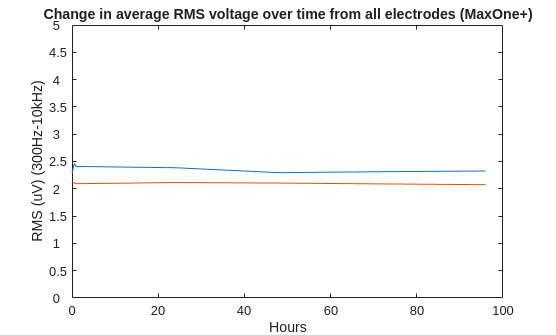

clf;
clear xlabel;
clear ylabel;

plot(timepoints,avPSD_RMSs_cells);
hold on;
plot(timepoints,avPSD_RMSs_media);
hold off;
ylim([0 5E-6]);
yt = get(gca,'YTick');
set(gca,'YTickLabel',yt*1E6);
xlabel('Hours');
ylabel('RMS (uV) (300Hz-10kHz)');


title('Change in average RMS voltage over time from all electrodes (MaxOne+)');

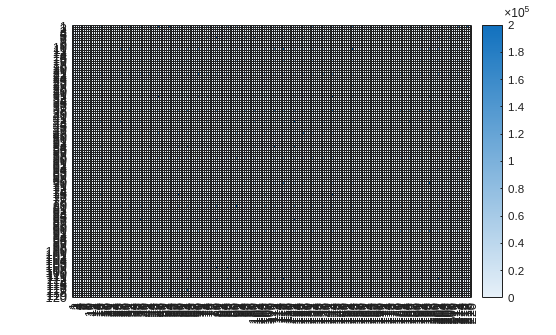

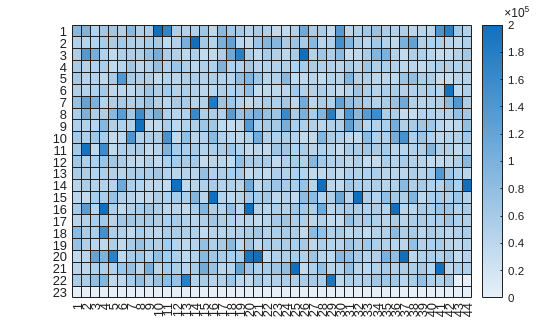

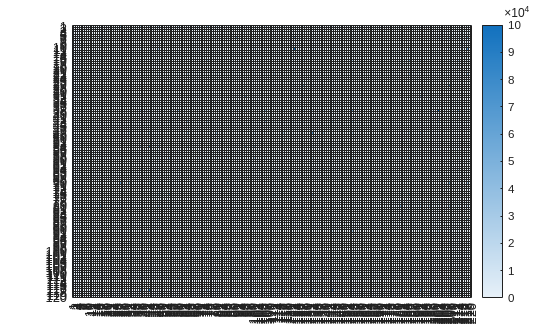

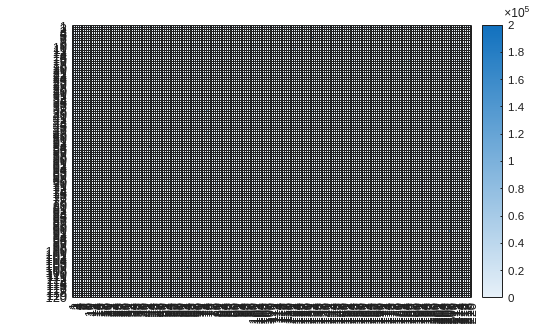

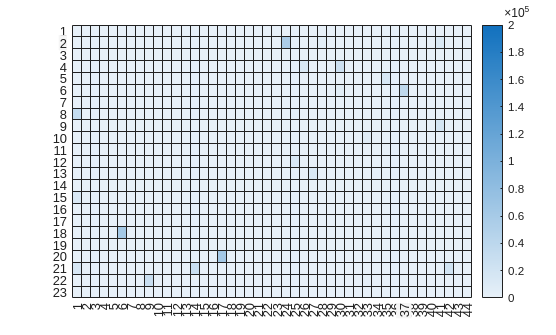

clf;

t1 = tiledlayout(1,2);
title(t1,'Average Input-Referred Noise Across All Electrodes');
nexttile;

loglog(freq,sqrt(PSD_media_media));
hold on;
loglog(freq,sqrt(PSD_media_T0));
hold off;

hold on;
loglog(freq,sqrt(PSD_media_T30));
hold off;
hold on;
loglog(freq,sqrt(PSD_media_T60));
hold off;

hold on;
loglog(freq,sqrt(PSD_media_D1));
hold off;
hold on;
loglog(freq,sqrt(PSD_media_D2));
hold off;
hold on;
loglog(freq,sqrt(PSD_media_D3));
hold off;
hold on;
loglog(freq,sqrt(PSD_media_D4));
hold off;
xlabel('Frequency (Hz)');
ylabel('Amplitude Spectral Density V/(Hz^{1/2})');
legend("Media Pre","Media T0","Media T30","Media T60","Media D1,","Media D2","Media D3","Media D4");
set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on');
xlim([300 9990]);

ax = gca;
colourMapLen = 7;
red = [1,0,0];
blue = [0,0,1];
colourGradient = [linspace(red(1),blue(1),colourMapLen)',linspace(red(2),blue(2),colourMapLen)',linspace(red(3),blue(3),colourMapLen)'];
ax.ColorOrder = cat(1,[0,0,0], colourGradient);

nexttile;
loglog(freq,sqrt(PSD_cells_media));


hold on;
loglog(freq,sqrt(PSD_cells_T0));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_T30));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_T60));
hold off;

hold on;
loglog(freq,sqrt(PSD_cells_D1));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D2));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D3));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D4));
hold off;

ax = gca;
ax.ColorOrder = cat(1,[0,0,0], colourGradient);
xlabel('Frequency (Hz)');
xlim([300 9990]);
set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on');
legend("Cells Pre","Cells T0","Cells T30","Cells T60","Cells D1","Cells D2","Cells D3","Cells D4");
%legend("Media T0","Media T60","Media D1,","Media D2","Media D3","Media D4","Cells T0","Cells T60","Cells D1","Cells D2","Cells D3","Cells D4","Cells Pre","Media Pre");

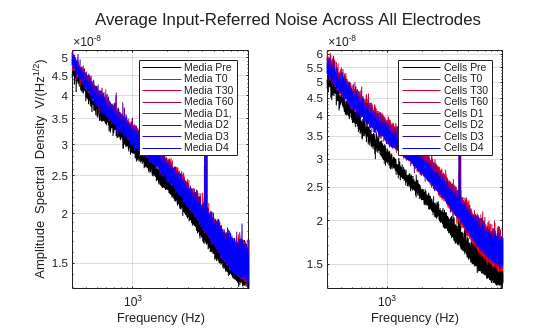

clf;

clf;




%loglog(freq,sqrt(diff_PSD_cells_T0));

loglog(freq,(diff_PSD_cells_T30));

hold on;
loglog(freq,(diff_PSD_cells_T60));
hold off;

hold on;
loglog(freq,(diff_PSD_cells_D1));
hold off;
hold on;
loglog(freq,(diff_PSD_cells_D2));
hold off;
hold on;
loglog(freq,(diff_PSD_cells_D3));
hold off;
hold on;
loglog(freq,(diff_PSD_cells_D4));
hold off;
legend("Cells T30","Cells T60","Cells D1","Cells D2","Cells D3","Cells D4");


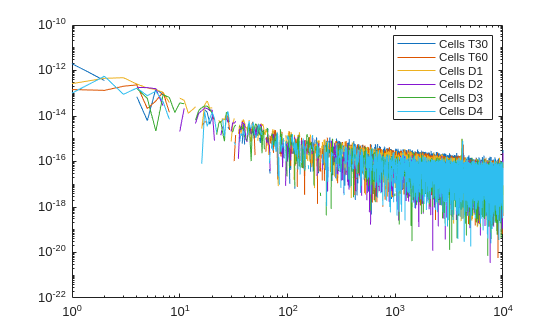

clf('reset');
[resistanceCellsD1,unmapped] = getLargeHeatmap(diff_PSDs_cells_D1,freqs,rawData_cells_D1);


heatmap(resistanceCellsD1,'ColorLimits',[0 200000]);


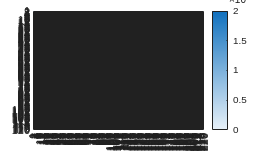



function [rawTracesSubset] = getRawTracesSubset(rawData,electrodes,numSeconds,correction)

   
    fs = 20000;
    
    [rawTraces,~,~] = rawData.extractRawData(fs,(numSeconds*fs),'files',1);
    rawTracesSubset = rawTraces(:,electrodes);
   
    rawTracesSubset = (rawTracesSubset./(1000000)).*correction;

    %returns input-referred traces with correction factor




end

function [filteredTraces] = getFilteredTraces(rawTraces,fc)

    fs = 20000;

    [sos,g] = butter(1,(fc)/(fs/2),"high");
    filteredTraces = filtfilt(sos,g,rawTraces);
end

function [avPSD,freqs,PSDs,avPSD_RMS,diffPSDs,avDiffPSDs] = getPSDs(filteredTraces,numSeconds,controlPSD)

    fs = 20000;
    %resolution = 1/numSeconds;
    resolution = 1;
    nfft = fs/resolution;
    window = hann(nfft); %len?
    overlap = 0;

    
    [PSDs,freqs] = pwelch(filteredTraces,window,overlap,nfft,fs);

    diffPSDs = PSDs - controlPSD;
    avDiffPSDs = sum(diffPSDs,2)/size(diffPSDs,2);

    avPSD = sum(PSDs,2)/size(PSDs,2);

    avPSD_RMS = sqrt(trapz(freqs(300:end-1),avPSD(300:end-1)));
    disp(avPSD_RMS);
end

function [PSD,freq,PSDs,avPSD_RMS,diffPSDs,avDiffPSDs] = processRawData(rawData,electrodes,numSeconds,correction,controlPSD)
    rawTracesSubset = getRawTracesSubset(rawData,electrodes,numSeconds,correction);
    filteredTraces = getFilteredTraces(rawTracesSubset,0.1);
    [PSD,freq,PSDs,avPSD_RMS,diffPSDs,avDiffPSDs] = getPSDs(filteredTraces,numSeconds,controlPSD);
end


function [heatmapData,unmappedData] = getHeatmap (PSDs, freqs)

    electrodeSize = 1012;
    PSDs(:,end + 1:electrodeSize) = 0;

    if size(PSDs,2) == electrodeSize

        freqs = repmat(freqs,1,electrodeSize);
        PSDs_RMS = zeros(electrodeSize,1);
        

        for i = 1:electrodeSize
            PSDs_RMS(i) = sqrt(trapz(freqs(200:3500,i),PSDs(200:3500,i)));
        end

        %IR_Electrode_PSD_RMS = ((((PSDs_RMS./gain).^2) - ((2.2E-6).^2))).^(1/2);
        %IR_Electrode_PSD_RMS = PSDs_RMS./gain;
        

        PSDs_RMS = real((max(PSDs_RMS,0)));

        bandwidth = 3500-200;
        boltzman = 1.38E-23;
        temp = 310; % 37 degree C in kelvin

        resistances = (PSDs_RMS.^2)./(4*boltzman*temp*bandwidth);
        
        mappedResistances = getMappedElectrodes(resistances);
        heatmapData = mappedResistances;
        
        unmappedData = resistances;


    else
        disp("Need all electrodes for heatmaps.")
    end
end


function [heatmapData,unmappedData] = getLargeHeatmap (PSDs, freqs, rawData)

    electrodeSize = 966;

    electrodeNums= rawData.rawMap(1).map.electrode(1:electrodeSize);
    
    PSDs = transpose(PSDs);
    PSD_rows = num2cell(PSDs,2);

    PSD_table = table(electrodeNums,PSD_rows);
    [~,idx] = sort(PSD_table.electrodeNums);
    sortedPSDtable = PSD_table(idx,:);

    sortedPSDs = transpose(cell2mat(PSD_table.PSD_rows));
    %sortedPSDs = PSDs;


    freqs = repmat(freqs,1,electrodeSize);
    PSDs_RMS = zeros(electrodeSize,1);

    for i = 1:electrodeSize
           PSDs_RMS(i) = sqrt(trapz(freqs(200:3500,i),sortedPSDs(200:3500,i)));
    end

    PSDs_RMS = real((max(PSDs_RMS,0)));

    bandwidth = 3500-200;
    boltzman = 1.38E-23;
    temp = 310; % 37 degree C in kelvin

    resistances = (PSDs_RMS.^2)./(4*boltzman*temp*bandwidth);
    unmappedData =resistances;

    mappedZeros = (zeros(26400,1));



    mappedZeros(transpose(sortedPSDtable.electrodeNums+1)) = 1;
    %mappedZeros(electrodeNums+1) = 1;
    index = 1;
    for i = 1:26400
        
        if mappedZeros(i) == 1
            mappedZeros(i) = resistances(index);
            index = index+ 1;
        end

    end
    heatmapData = getMappedElectrodeOverlay(mappedZeros);



end

function mappedElectrodes = getMappedElectrodes(electrodes)
    mappedElectrodes = zeros([23,44]);
    
    for i = 1:23
        x = (i-1)*44;
        y = i*44;
        mappedElectrodes(i,1:44) = transpose(electrodes(x+1:y));
    end
end

function mappedElectrodes = getMappedElectrodeOverlay(electrodes)
        
    mappedElectrodes = zeros([120,220]);
    
    for i = 1:120
        x = (i-1)*220;
        y = i*220;
        mappedElectrodes(i,1:220) = transpose(electrodes(x+1:y));
    end
end